# Actividad 3: Evaluación

Víctor Manuel Vázquez Morales A01736352

%Limpieza de pantalla
clear all
close all
clc

**Ejercicio 2: **

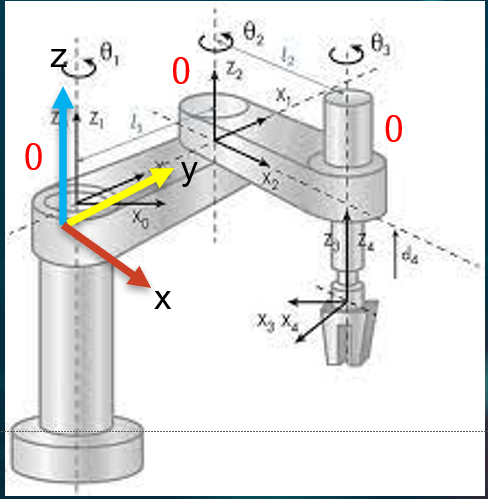

Para este ejercicio, notemos que se ven involucradas las siguientes variables: 

- theta 1: Angulo de rotación en la primera junta

- theta 2: : Angulo de rotación en la segunda junta

- theta 3: Angulo de rotación en la tercera junta

%Declaración de variables simbólicas 
syms th1(t) th2(t) th3(t) l1 l2 l3 h

%configuracion del robot, 0 para junta rotacional y 1 para prismatica 
RP=[0 0 0]; 

%Vector de coordenadas articulares
Q = [th1,th2, th3]; 
disp('Coordenadas articulares'); 

Coordenadas articulares


pretty(Q);

(th1(t), th2(t), th3(t))



%vector de velocidad articulares
Qp = diff(Q,t); %se utiliza diff para derivadas cuya variable no depende de otras
disp('Velocidades articulares'); 

Velocidades articulares


pretty(Qp); 

/  d          d          d        \
| -- th1(t), -- th2(t), -- th3(t) |
\ dt         dt         dt        /




%numero de grado de libertad del robot
GDL = size(RP,2); %se coloca 2 para referirse a las columnas de la matriz 
GDL_str = num2str(GDL); %convertir numero a string

**Articulación 1: **

Para la primera articulación, hay una rotación sobre el eje z. 

En este caso, el vector de traslación viene dado por: 

%posicion de la junta 1 respecto a 0
P(:,:,1) = [l1*cos(th1);
            l1*sin(th1); 
            0];  

Mientras que la matriz de rotación es: 

% Definir la matriz de rotación original R(:,:,1)
R(:,:,1) = [cos(th1) -sin(th1) 0; 
            sin(th1) cos(th1) 0; 
             0           0     1];

**Articulación 2: **

De manera similar a la anterior circulación, tenemos una rotación en en el eje z, por lo que la matriz de transformación estará dada por: 

%Articulación 2
%posicion de la junta 2 respecto a 1
P(:,:,2) = [l2*cos(th2); 
            l2*sin(th2); 
            0]; 

%matriz de rotacion de articulacion 2

R(:,:,2) = [cos(th2) -sin(th2) 0; 
            sin(th2) cos(th2) 0; 
             0           0     1];   

**Articulación 3: **

Para este último caso, existe de igual forma una rotación sobre el eje z. Sin embargo, observemos que esta ultima junta es de revolución, por lo tanto su vector de traslación será una constante en z: 


%Articulación 3
%posicion de la junta 3 respecto a 2
P(:,:,3) = [0; 0; h];  

Al ya no contar con una siguiente articulación, no es necesario rotar el sistema, por tanto, agregamos la matriz identidad a nuestra matriz de rotación: 

%matriz de rotacion de articulacion 3
R(:,:,3) = [cos(th3) -sin(th3) 0; 
            sin(th3) cos(th3) 0; 
             0           0     1]; 

**Cálculo de velocidades lineales y angulares: **


Vector_Zeros = zeros(1,3); 

%inicializamos matriz de transformacion homogenea local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%inicializamos matriz de transformacion homogenea global ()
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

PO(:,:,GDL)= P(:,:,GDL); %vectores de posicion vistos desde el marco de referencia inercial

RO(:,:,GDL)= R(:,:,GDL); %matrices de rotacion distas desde el marco de referencia inercial

for i= 1: GDL
    i_str = num2str(i);
    %locales
    %disp(strcat('Matriz de transformacion local A',i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    %pretty (A(:,:,i));

    %globales
    try 
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch 
        T(:,:,i) = A(:,:,i); %caso especifico cuando i= 1 nos marcaria error en try
    end 
    disp(strcat('Matriz de transformacion global T',i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %obtenemos la matriz de rotacion RO y el vector de translacion PO de la
    %matriz de transformacion homogenea global T(:,:,GDL)

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end 

Matriz de transformacion global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de transformacion global T2


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                          |
| l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                          |
\                     0                    /



Matriz de transformacion global T3


/ #2, -#1, 0, l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                                      |
| #1,  #2, 0, l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                                      |
|  0,  0,  1,                     h                    |
|                                                      |
\  0,  0,  0,                     1                    /

where

   #1 == sin(th1(t) + th2(t) + th3(t))

   #2 == cos(th1(t) + th2(t) + th3(t))




/ cos(th1(t) + th2(t) + th3(t)), -sin(th1(t) + th2(t) + th3(t)), 0 \
|                                                                  |
| sin(th1(t) + th2(t) + th3(t)),  cos(th1(t) + th2(t) + th3(t)), 0 |
|                                                                  |
\               0,                              0,               1 /



/ l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                          |
| l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                          |
\                     h                    /




%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   _________                               _________    \
|    d                                       d           |
| - -- th1(t) (l1 sin(th1(t)) + l2 #1) - l2 -- th2(t) #1 |
|   dt                                      dt           |
|                                                        |
|  _________                               _________     |
|   d                                       d            |
|  -- th1(t) (l1 cos(th1(t)) + l2 #2) + l2 -- th2(t) #2  |
|  dt                                      dt            |
|                                                        |
\                            0                           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/                 0                 \
|                                   |
|                 0                 |
|                                   |
| _________   _________   _________ |
|  d           d           d        |
| -- th1(t) + -- th2(t) + -- th3(t) |
\ dt          dt          dt        /



Finalmente, analicemos los resultados: 

**Velocidad lineal: **

Observemos que para este caso, la velocidad lineal en el eje x y el eje y están siendo afectadas por las longitudes de los brazos, asi como el valor de los ángulos. Notemos que para x, todo esta en función de seno, debido a que se obtuvo de derivar el coseno, el cual se estableción por las identidades trigonometricas. Del mismo modo, observemos que para el eje y tenemos todo en función de coseno, obtenido de derivar el seno, el cual ese estableció en las matrices de transformación segun las identidades trigonometricas. 

Por último, recordemos que no hay movimiento sobre el eje z, por lo que la velocidad lineal para este eje no existe

**Velocidad angular: **

Para este último caso, notemos que la velocidad angular en el eje x y eje y son nulas, esto debido a que ninguna articulación gira sobre estos ejes. Ahora bien, para el caso del eje z, tenemos que la velocidad angular esta dada por la sumatoria de las tres diferenciales del ángulo con respecto al tiempo. Esto hace sentido debido a que tenemos tres juntas (con distintos thetas) rotando en este eje. 